# Exercise 2: Create and Train Agent

## Load Environment Info

First, load the environment object that you created in Exercise 1.

load("EnvironmentInfo.mat");

Load the Simulink model used for training.

mdl = "HumanoidWalkerRobot";
open_system(mdl);

## Design Agent

In this exercise, we will design an RL agent interactively using the Reinforcement Learning Designer app. Open the app.

reinforcementLearningDesigner;

We first need to import the environment that we just defined. Select **Import **> `env`.

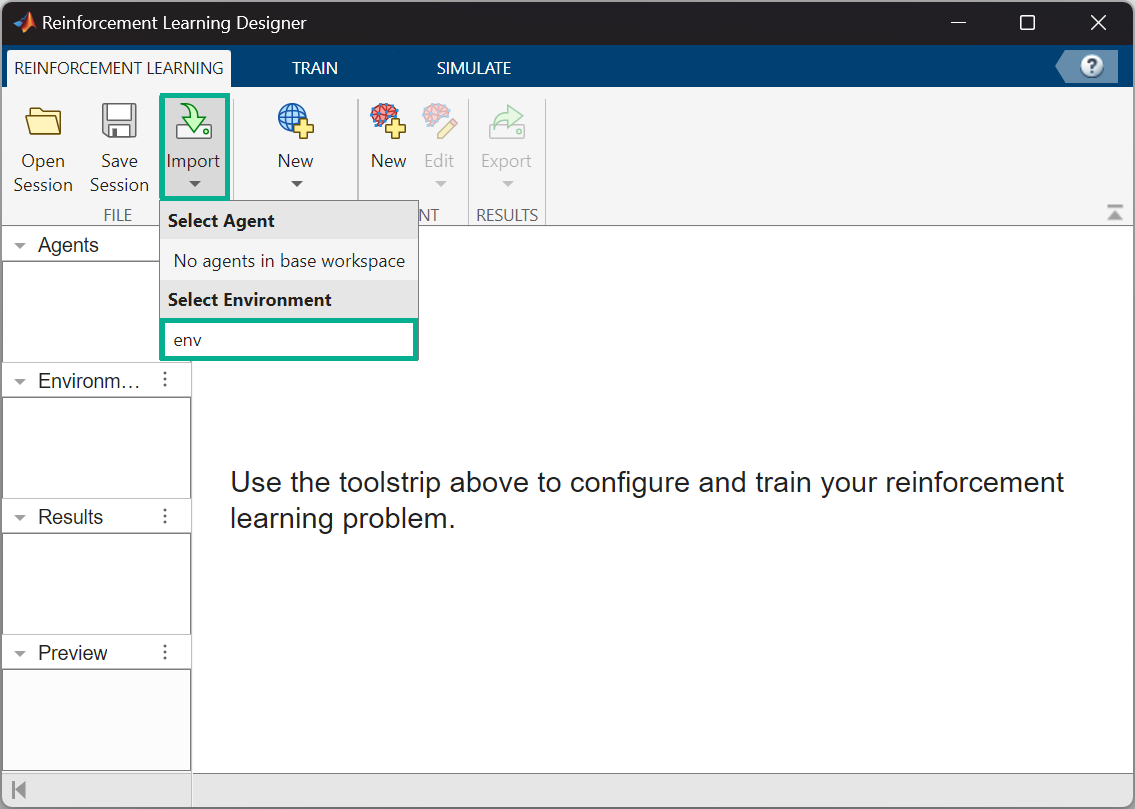

### Create TD3 Agent

Now we can begin creating the agent. In the **Agent** pane, select **New**.

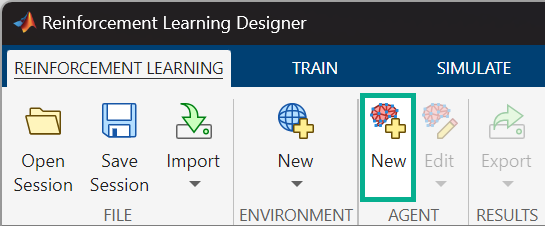 

This opens a new dialog where you can define some basic information for the agent, as follows:

- Set the **Agent name** to **agent1**.

- Make sure the **Environment** is set to **env**.

- MATLAB has already filtered our algorithm options based on what is compatible with the environment that we've specified (e.g., a continuous action space). Under **Compatible algorithm**, select **TD3**.

-  Finally, the **Neural network parametrizations** field allows us to specify some high-level information on the neural network architecture, like how many nodes should be used in hidden fully connected layers and whether the policy network should have recurrent layers. Set **Number of hidden units** to **400** and **uncheck** the **Use recurrent neural network** option.

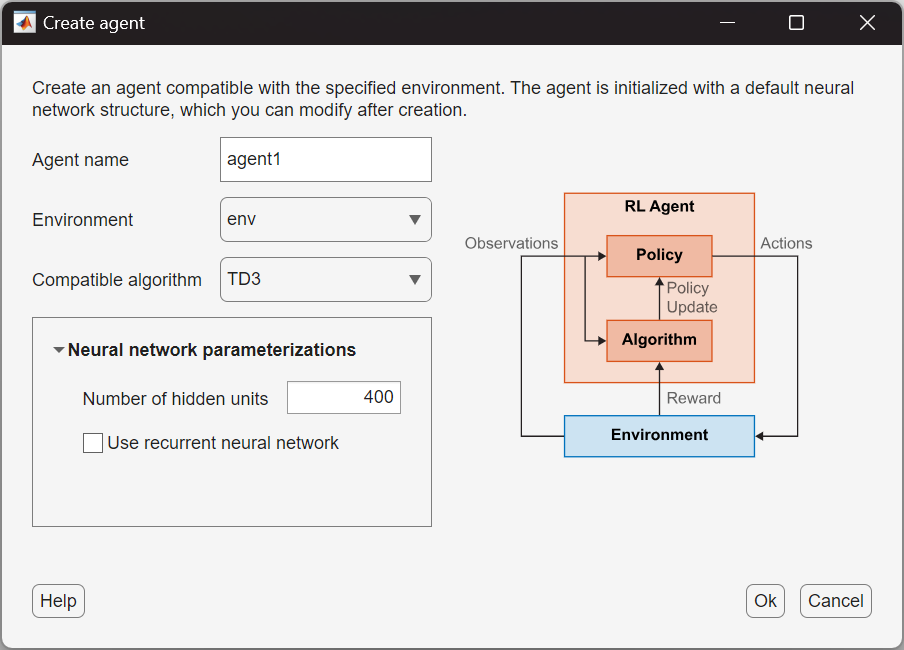

Select **Ok**.

### Tune Agent Options

A new tab will open with information on the agent you've just created, as well as various hyperparameters and options you can set. 

Set the **Sample time** to **0.025**, and leave the rest of the parameters set to their default values.

Now take a look at the **Exploration Model **section.

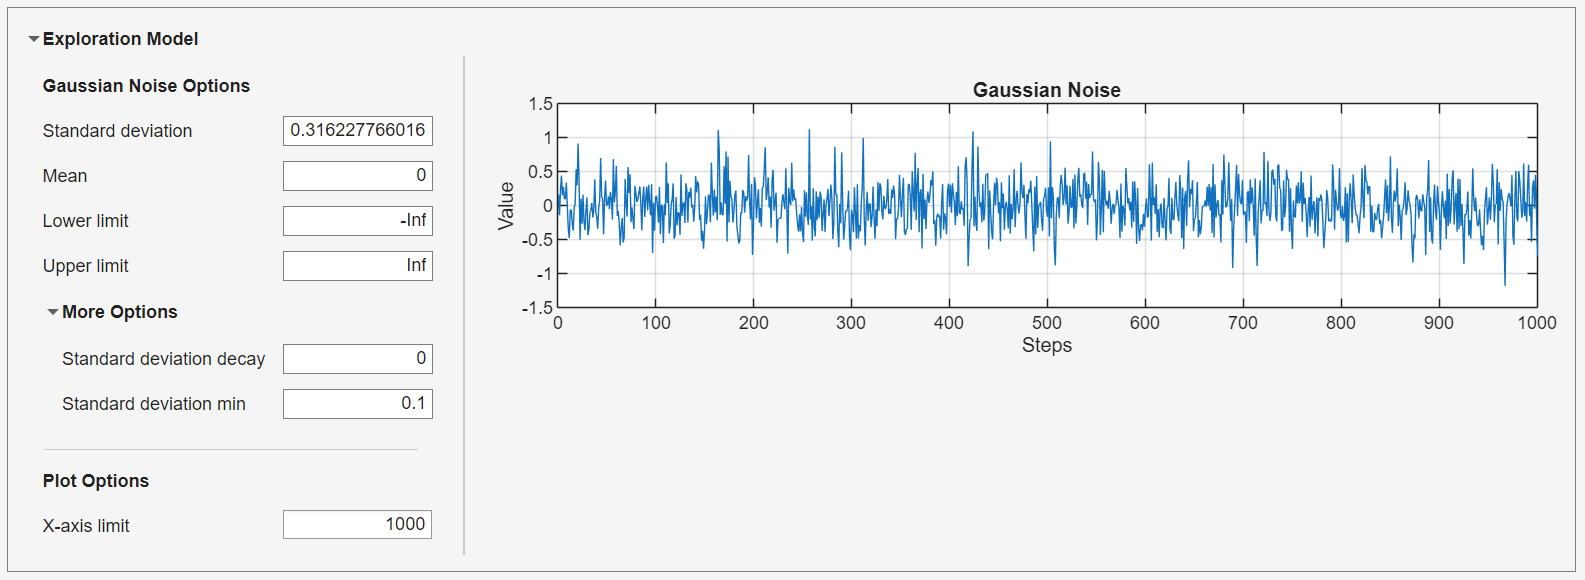

TD3 agents perform exploration by adding random Gaussian noise to the action output at each step. The amount of noise applied is typically reduced over time by decaying the standard deviation used for the Gaussian noise distribution.

## Train Agent

Now that we've fully defined our agent, we are ready to train it. The training process can be very computationally intensive, often taking several hours for complex tasks. We will only run a handful of episodes to see what the training process looks like.

Navigate to the **Train** tab and set the training options to the values shown below. Then select **Train**.

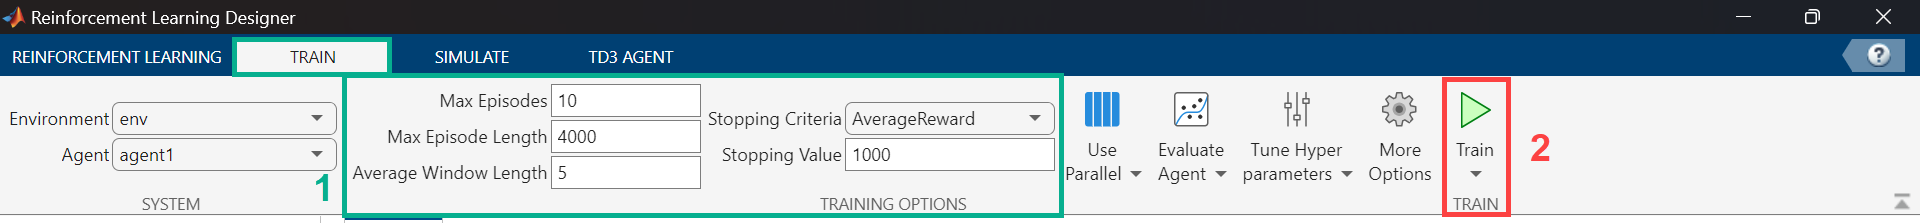

Make sure to open the Multibody Explorer during training to observe the agent's behavior.

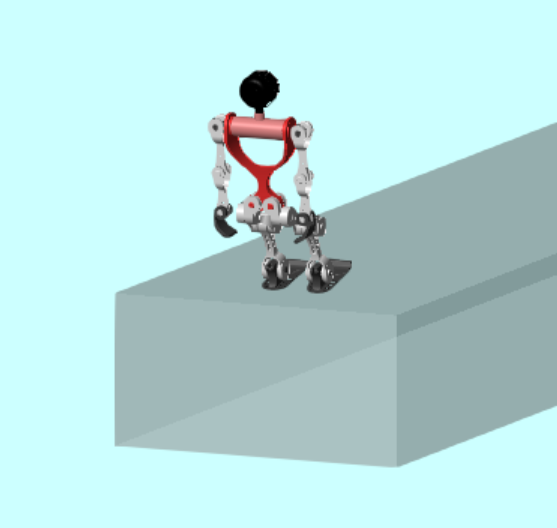

Observe the **Training Results** tab to see how the reward changes over time.

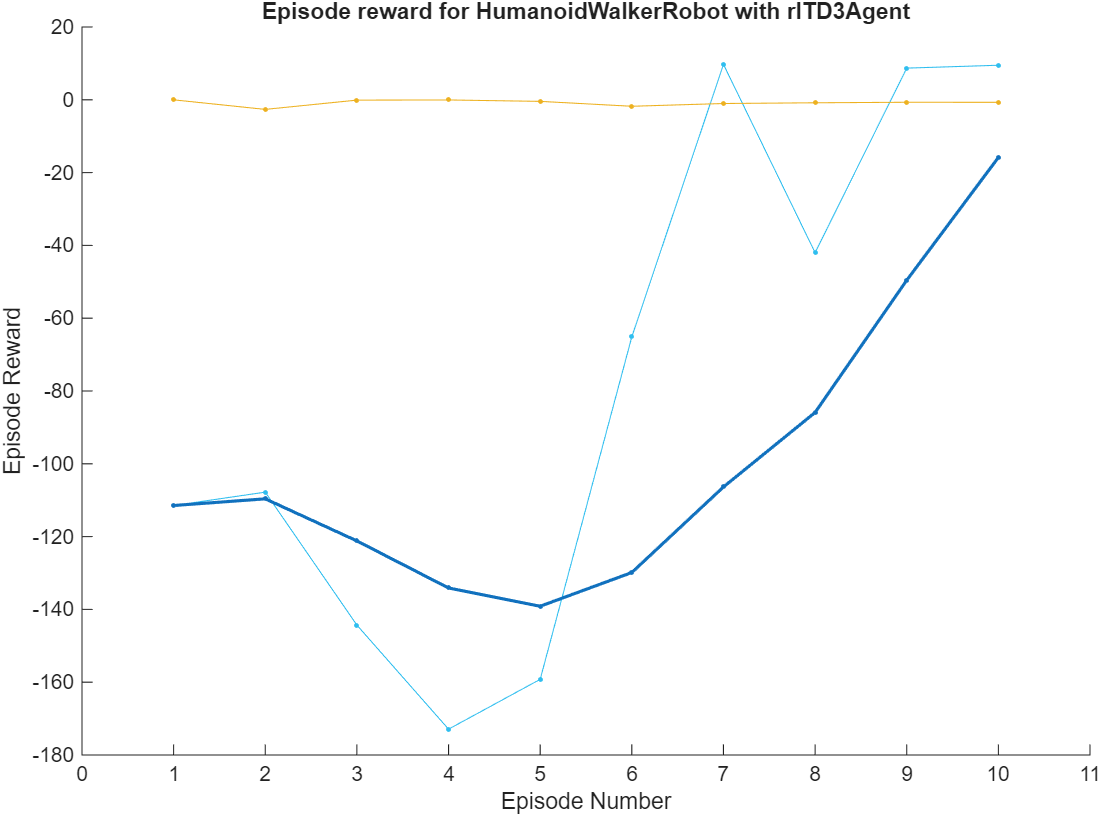

## Bonus tasks

- Try changing agent hyperparameters (learn rate, exploration settings, etc.) and see how they affect the agent's learning performance.

- Try running a longer training to see how training/validation episode reward evolves over time.

*Copyright 2019-2025 The MathWorks, Inc.*